# Co-occurrence analysis with Text Analysis Toolbox

One of the most common applications of text analytics is performing co-occurrence analysis. Here is an example of performing the analysis with MATLAB. **Note: Text Analytics Toolbox is required to run the codes in this example.**

## Functions for Co-occurrence analysis

The following three functions are provided.

- createCOTable.m

- createCONetwork.m

- visualizeCO.m

### createCOTable.m

This function creates a co-occurence table for given keywords. It finds top N most frequently occurring words (co-occurrence words) and their frequency within given span for given keywords. It also calculates T-value and MI-value for each co-occcurence words.

### createCONetwork.m

This function creates a Co-occurrence network from the co-occurence table created by createCOTable.m. 

### visualizeCO.m

This function is to visualize the co-occurence network created by createCONetwork.m

For detaile of these functions, refer to each M-file, or use doc/help function.

## Example

Let's see how it works. We use the sample data 'weatherReports.csv', which is provided with Text Analytics Toolbox R2019b.  (As an alternative sample file, 'FactoryReports.csv' can be used for R2020a. Un-comment line 2 and 7.) 

### Preparation

First, import the sample data file into a table. 

fileName = 'WeatherReports.csv'; % For MATLAB R2019b 
% fileName = 'FactoryReports.csv'; % For MATLAB R2020a

data = readtable(fileName,'TextType','string');
head(data) 

ans = 8×16 table
             Time              event_id          state              event_type         damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon                                                                                             event_narrative                                                                                             storm_duration    begin_day    end_day    year       end_timestamp    
    ______________________    __________    ________________    ___________________    _______________    ____________    _________    _________    _______    _______    _________________________________________________________________________________________________________________________________________________________________________________________________    ______________    _________    _______    ____    ____________________

    "22-Jul-2016 16:10:00"    6.4433e+05    "MISSISSIPPI"       "Thunderstorm Wind"       ""              

Then, extract the text data from the column "event_narrative", and perform tokenizeation and other pre-processing (removing punctuation, etc...)

textData = data.event_narrative; % For MATLAB R2019b
% textData = data.Description; % For MATLAB R2020a

docs = tokenizedDocument(textData);
docs = addPartOfSpeechDetails(docs);
docs = erasePunctuation(docs);
docs = removeStopWords(docs);
docs = removeShortWords(docs,2);
docs = removeLongWords(docs,15);
docs = removeEmptyDocuments(docs);
docs = addLemmaDetails(docs);

### Creating co-occurence table

Now, we're ready to do co-occurence analysis. First, we need to define some parameters.  

The first one is the number of keywords, for which the co-occuring words are sought.  Here, we selected top four most occurring words in the data as keywords.  (The function also allows users to define the keywords as a cell array of words.)

nKeywords = 4;

The next parameter is the span, which is the length of the window in which the co-occuring words are sought.

span = 4;

The parameter "nCooc" defines the number of co-occuring words sought for each keywords.

nCooc = 5;

The last one, 'mode', defines the location of the keywords within the span. 

mode = 'center';

Then, we create the co-occurrence table.

COTable   = createCOTable(docs,span, nKeywords, nCooc, mode)

COTable = 20×7 table
       Word       Counts      COWord      COCount    COCountAll       T         MI  
    __________    ______    __________    _______    __________    _______    ______

    "reported"     9640     "inches"        635         7755       -9.0278    10.768
    "reported"     9640     "hail"          380         3312       -6.9837    11.254
    "reported"     9640     "size"          222         1917       -5.3379    11.268
    "reported"     9640     "snow"          217         4344       -5.2774    10.055
    "reported"     9640     "spotter"       180          903       -4.8065    12.051
    "inches"       7755     "snow"          731         4344       -2.5054    11.807
    "inches"       7755     "reported"      652         9640       -2.3661    10.492
    "inches"       7755     "measured"      542         3288       -2.1573    11.777
    "inches"       7755     "rain"          469         2032       -2.0068    12.263
    "inches"       7755     "rainfall"     

The columns of the table represent the following.

- Word: keyword for which co-occurring words are sought

- Counts: occurence of the keyword in the entire document

- COWord: co-occuring word within the span of the keyword

- COCount: occurrence of the COWord within the span of the keyword

- COCountAll: occurence of the COWord in the entire data

- T : T-value

- MI: MI-value

### Create and visualize co-occurence network

Once we create the co-occurence table, it is straightforward to create co-occurence network and associated diagram.

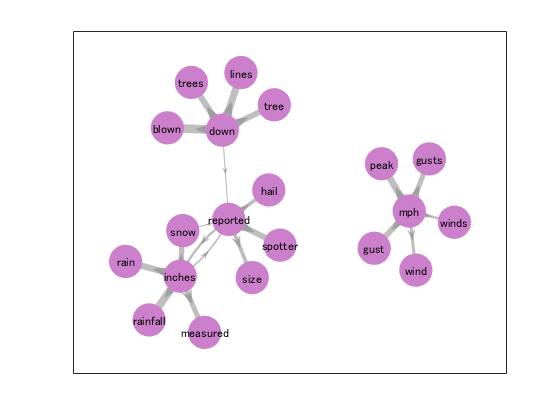

CONetwork = createCONetwork(COTable,'MI');

visualizeCO(CONetwork,'NodeColor',[0.8 0.5 0.8],'FontSize',9,'MarkerSize',24);

You can also specify the edge color and edge width

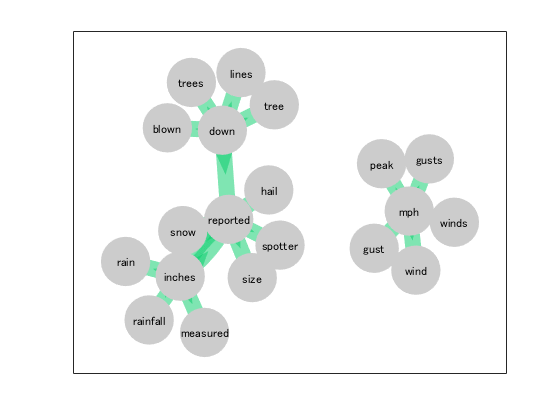

visualizeCO(CONetwork,'EdgeColor',[0 0.8 0.4],'EdgeWidth',12);

Another example.

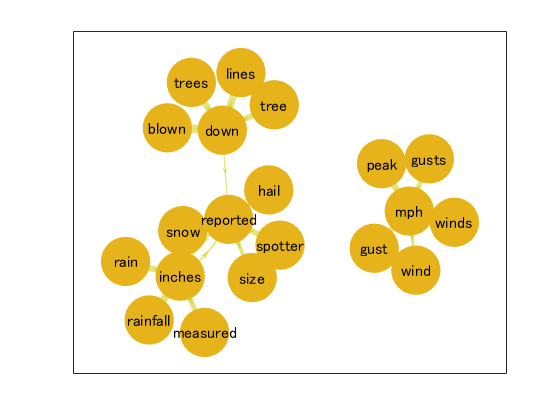

visualizeCO(CONetwork,'NodeColor',[0.9 0.7 0.1],'FontSize',12,'MarkerSize',36,'EdgeColor',[0.8 0.8 0]);

*Copyright 2020 The MathWorks, Inc.*